# Lab 5 by Cole Bardin 		Section: 61

## Method of Undetermined Coefficients

## Part A: Homogeneous DE

clc, clear, close all
% Question 2
syms y(t)
Dy = diff(y,t); D2y = diff(y,t, t);

DE = 4*D2y +4*Dy + 17*y == 0;
sol = dsolve(DE, y(0)==4, Dy(0)==0)

$$sol = {\mathrm{e}}^{-\frac{t}{2}}\,\left(4\,\cos\left(2\,t\right)+\sin\left(2\,t\right)\right)$$


% Question 3

Y = matlabFunction(sol);
Dy = matlabFunction(diff(Y, t));

Y(1)

ans = -0.4581

Dy(1)

ans = -4.6879

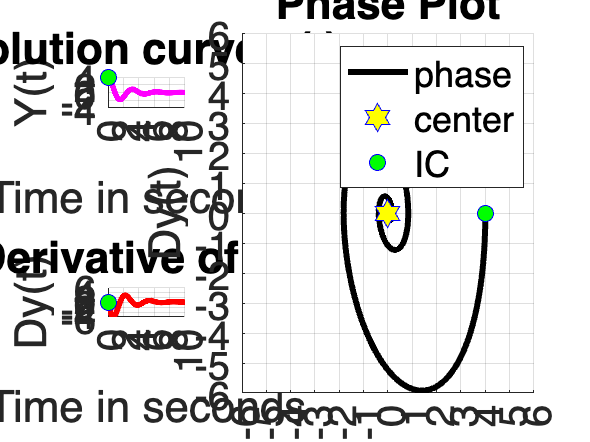


% Questions 4-5
figure
time = 0: 0.01 : 10;

subplot(2,3,1) % tile 1
set(gca,"FontSize",20)
hold on
grid on
plot(time, Y(time), 'm', 'LineWidth',3)
plot(0,4, 'bo', 'MarkerSize',8, 'MarkerFaceColor','g')
title("Solution curve y(t)")
xlabel("Time in seconds")
ylabel("Y(t)")
axis([0, 10, -4, 4])
xticks(0:2:10)
yticks(-4:2:4)

subplot(2, 3, 4) % tile 4
set(gca,"FontSize",20)
hold on
grid on
plot(time, Dy(time), 'r', 'LineWidth',3)
plot(0,0, 'bo', 'MarkerSize',8, 'MarkerFaceColor','g')
title("Derivative of y(t)")
xlabel("Time in seconds")
ylabel("Dy(t)")
axis([0, 10, -6, 6])
xticks(0:2:10)
yticks(-6:2:6)

subplot(2, 3, [2, 3, 5, 6]) % 2-3 and 5-6
set(gca,"FontSize",20)
hold on
grid on
phase = plot(Y(time), Dy(time), 'k', 'LineWidth',3);
center = plot(0, 0, 'bh', 'MarkerSize', 14, 'MarkerFaceColor', 'yellow'); % Center Point
ic = plot(4,0, 'bo', 'MarkerSize',8, 'MarkerFaceColor','g');
title("Phase Plot")
xlabel("Y(t)")
ylabel("Dy(t)")
axis([-6, 6, -6, 6])
xticks(-6:6)
yticks(-6:6)
legend([phase, center, ic], ["phase", "center", "IC"])

## Part B: Non-Homogeneous DE: Method of Undetermined Coefficients

clc, clear, close all
% Questions 6-7
syms y(t)
Dy = diff(y,t); D2y = diff(y,t, t);

% a)
DE = 4*D2y +4*Dy + 17*y == 17 + 289*t;
sol = dsolve(DE, y(0)==4, Dy(0)==0);
disp("a)")

a)


sol = simplify(sol)

$$sol = 17\,t+7\,\cos\left(2\,t\right)\,{\mathrm{e}}^{-\frac{t}{2}}-\frac{27\,\sin\left(2\,t\right)\,{\mathrm{e}}^{-\frac{t}{2}}}{4}-3$$

% b)
DE = 4*D2y +4*Dy + 17*y == 100*exp(-2*t);
sol = dsolve(DE, y(0)==4, Dy(0)==0);
disp("b)")

b)


sol = simplify(sol)

$$sol = 4\,{\mathrm{e}}^{-2\,t}+4\,\sin\left(2\,t\right)\,{\mathrm{e}}^{-\frac{t}{2}}$$

% c)
DE = 4*D2y +4*Dy + 17*y == 260*cos(2*t);
sol = dsolve(DE, y(0)==4, Dy(0)==0);
disp("c)")

c)


sol = simplify(sol)

$$sol = 4\,\cos\left(2\,t\right)+32\,\sin\left(2\,t\right)-32\,\sin\left(2\,t\right)\,{\mathrm{e}}^{-\frac{t}{2}}$$

% d)
DE = 4*D2y +4*Dy + 17*y == 16*exp(-t/2)*cos(2*t) + 32*exp(-t/2)*sin(2*t);
sol = dsolve(DE, y(0)==4, Dy(0)==0);
disp("d)")

d)


sol = simplify(sol)

$$sol = {\mathrm{e}}^{-\frac{t}{2}}\,\left(4\,\cos\left(2\,t\right)+2\,\sin\left(2\,t\right)-2\,t\,\cos\left(2\,t\right)+t\,\sin\left(2\,t\right)\right)$$

## Questions 8-10: The Method of Undetermined Coefficients from SCRATCH

clc, clear, close all
% Question 8
syms A B t C1 C2
syms y(t) a b
Dy = diff(y,t); D2y = diff(y,t, t);
f = 260*cos(2*t)

$$f = 260\,\cos\left(2\,t\right)$$

DE = 4*D2y + 4*Dy + 17*y - f == 0 % non-homogeneous differential equation

$$DE(t) = 4\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+4\,\frac{\partial }{\partial t}y\left(t\right)-260\,\cos\left(2\,t\right)+17\,y\left(t\right)=0$$


Y = A * cos(2*t) + B * sin(2*t) % our guess

$$Y = A\,\cos\left(2\,t\right)+B\,\sin\left(2\,t\right)$$

plug_it_in = subs(DE, y, Y) % Plug our guess into the DE

$$plug\_it\_in(t) = A\,\cos\left(2\,t\right)-260\,\cos\left(2\,t\right)+8\,B\,\cos\left(2\,t\right)-8\,A\,\sin\left(2\,t\right)+B\,\sin\left(2\,t\right)=0$$

eqn = collect(plug_it_in, [cos(2*t), sin(2*t)]) % arrange by similar terms

$$eqn(t) = \left(A+8\,B-260\right)\,\cos\left(2\,t\right)+\left(B-8\,A\right)\,\sin\left(2\,t\right)=0$$


% MATLAB can find the undetermined coefficients for us
equations = coeffs( lhs(eqn), [cos(2*t), sin(2*t)] )

$$equations(t) = \left(\begin{array}{cc} B-8\,A & A+8\,B-260 \end{array}\right)$$

variables = [A, B]

$$variables = \left(\begin{array}{cc} A & B \end{array}\right)$$

% find and display the undetermined coefficients
[A, B] = solve(equations, variables) 

$$A = 4$$

$$B = 32$$



% Questions 9-10
Yp = A * cos(2*t) + B * sin(2*t); % our guess;

% Solve for homogenous solution
DE = 4*D2y + 4*Dy + 17*y == 0;
Yh = simplify(dsolve(DE));

% Get general form
Y = simplify(Yh + Yp);
Dy = diff(Y, t);

% Solve for C1 and C2 in general form
Y = matlabFunction(Y);
Dy = matlabFunction(diff(Y,t));
eqns = [Y(sym(C1), sym(C2), 0)==4, Dy(sym(C1), sym(C2), 0)==0];
C = solve(eqns, C1, C2);

% Sub in C1 and C2 values
Y = simplify(Yh + Yp);
Y = subs(Y, C1, C.C1);
Y = subs(Y, C2, C.C2);

% Make new matlab functions for new solutions
Y = matlabFunction(Y)

Y = function_handle with value:
    @(t)cos(t.*2.0).*4.0+sin(t.*2.0).*3.2e+1-sin(t.*2.0).*exp(t.*(-1.0./2.0)).*3.2e+1


Dy = matlabFunction(diff(Y,t))

Dy = function_handle with value:
    @(t)cos(t.*2.0).*6.4e+1-sin(t.*2.0).*8.0-cos(t.*2.0).*exp(t.*(-1.0./2.0)).*6.4e+1+sin(t.*2.0).*exp(t.*(-1.0./2.0)).*1.6e+1


Yp = matlabFunction(Yp)

Yp = function_handle with value:
    @(t)cos(t.*2.0).*4.0+sin(t.*2.0).*3.2e+1


Ypp = matlabFunction(diff(Yp, t))

Ypp = function_handle with value:
    @(t)cos(t.*2.0).*6.4e+1-sin(t.*2.0).*8.0


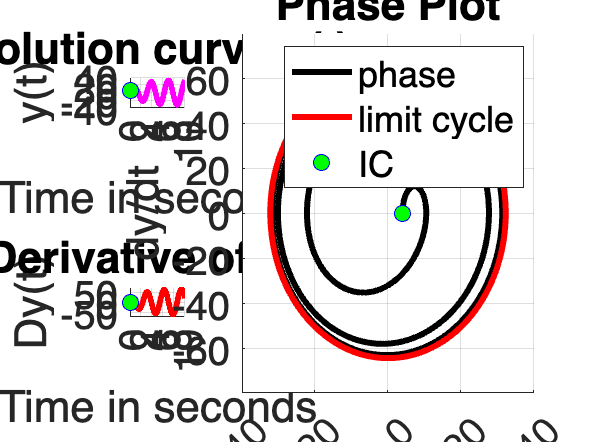


fig3 = figure(3);
time = 0: 0.01 : 10;

subplot(2,3,1) % tile 1
set(gca,"FontSize",20)
hold on
grid on
plot(time, Y(time), 'm', 'LineWidth',3)
plot(0,4, 'bo', 'MarkerSize',8, 'MarkerFaceColor','g')
title("Solution curve y(t)")
xlabel("Time in seconds")
ylabel("y(t)")
axis([0, 10, -40, 40])
xticks(0:2:10)
yticks(-40:20:40)

subplot(2, 3, 4) % tile 4
set(gca,"FontSize",20)
hold on
grid on
plot(time, Dy(time), 'r', 'LineWidth',3)
plot(0,0, 'bo', 'MarkerSize',8, 'MarkerFaceColor','g')
title("Derivative of y(t)")
xlabel("Time in seconds")
ylabel("Dy(t)")
axis([0, 10, -75, 75])
xticks(0:2:10)
yticks(-50:50:50)

subplot(2, 3, [2, 3, 5, 6]) % 2-3 and 5-6
set(gca,"FontSize",20)
hold on
grid on
phase = plot(Y(time), Dy(time), 'k', 'LineWidth',3);
ic = plot(4,0, 'bo', 'MarkerSize',8, 'MarkerFaceColor','g');
limit = plot(Yp(time), Ypp(time), 'r', 'LineWidth',3);
title("Phase Plot")
xlabel("y(t)")
ylabel("dy/dt")
axis([-40, 40, -80, 80])
xticks(-40:20:40)
yticks(-60:20:60)
legend([phase, limit, ic], ["phase", "limit cycle", "IC"])